# Fourier series

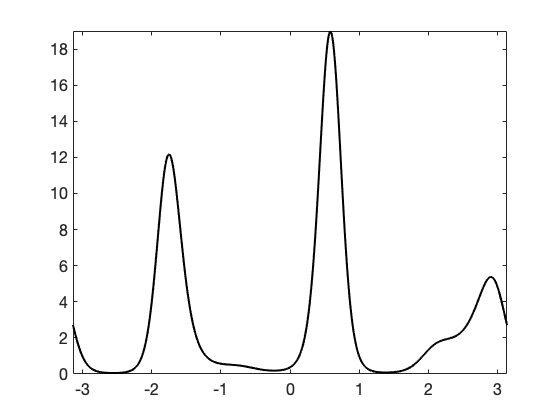

f = @(x) exp( 2*sin(3*x) - 1*cos(5*x) );
fplot(f,[-pi pi],'k','linew',2)

u = @(k,x) exp(1i*k*x) / sqrt(2*pi);
c0 = integral(@(x) conj(u(0,x)).*f(x),-pi,pi);
for k = 1:20 
    cplus(k) = integral(@(x) conj(u(k,x)).*f(x),-pi,pi);
    cminus(k) = integral(@(x) conj(u(-k,x)).*f(x),-pi,pi);
end

## sum k from -2 to 2

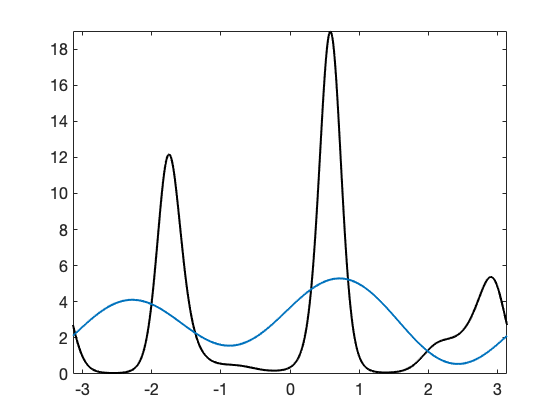

x = linspace(-pi,pi,500);
s = c0*u(0,x);
for k = 1:2 
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)

## from -6 to 6

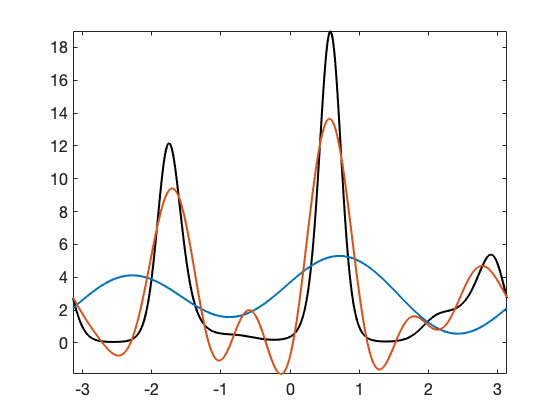

x = linspace(-pi,pi,500);
s = c0*u(0,x);
for k = 1:6
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)

## from -12 to 12

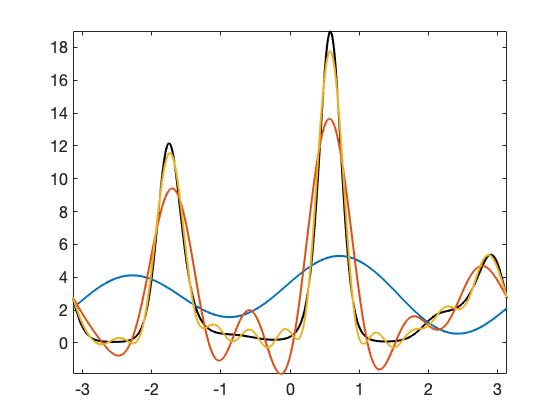

x = linspace(-pi,pi,500);
s = c0*u(0,x);
for k = 1:12
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)

## from -20 to 20

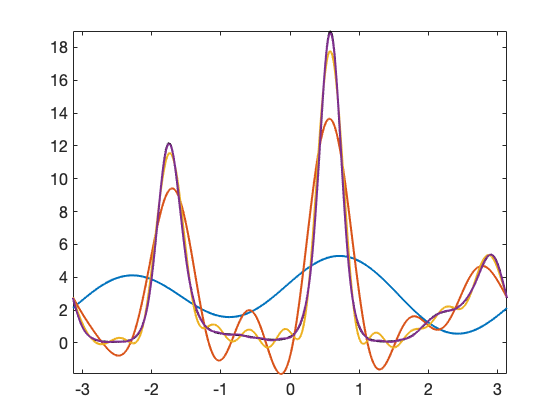

x = linspace(-pi,pi,500);
s = c0*u(0,x);
for k = 1:20
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)